%Creamo un objeto: 
fuzziFIS = mamfis( ...
    'Name','Uses Binary MFs', ...
    'NumInputs', 2, 'NumInputMFs',3, ...
    'NumOutputs', 1, 'NumOutputMFs', 3, ...
    'AddRule', 'none' ...
    ); 

%Humedad: 
fuzziFIS.Inputs(1).Name = 'Humedad'; 
fuzziFIS.Inputs(1).Range = [0 10]; 
fuzziFIS.Inputs(1).MembershipFunctions(1).Name = 'B';
fuzziFIS.Inputs(1).MembershipFunctions(1).Type = 'gaussmf';
fuzziFIS.Inputs(1).MembershipFunctions(1).Parameters = [1.617 0];
fuzziFIS.Inputs(1).MembershipFunctions(2).Name = 'Op';
fuzziFIS.Inputs(1).MembershipFunctions(2).Type = 'gaussmf';
fuzziFIS.Inputs(1).MembershipFunctions(2).Parameters =  [0.397 6];
fuzziFIS.Inputs(1).MembershipFunctions(3).Name = 'A';
fuzziFIS.Inputs(1).MembershipFunctions(3).Type = 'gaussmf';
fuzziFIS.Inputs(1).MembershipFunctions(3).Parameters =   [1.271 10];

%Probabilidad de lluvia: 
fuzziFIS.Inputs(2).Name = 'Prb_lluvia'; 
fuzziFIS.Inputs(2).Range = [0 10]; 
fuzziFIS.Inputs(2).MembershipFunctions(1).Name = 'B';
fuzziFIS.Inputs(2).MembershipFunctions(1).Type = 'gaussmf';
fuzziFIS.Inputs(2).MembershipFunctions(1).Parameters =  [2.237 0];
fuzziFIS.Inputs(2).MembershipFunctions(2).Name = 'Md';
fuzziFIS.Inputs(2).MembershipFunctions(2).Type = 'gaussmf';
fuzziFIS.Inputs(2).MembershipFunctions(2).Parameters =   [0.6292 6];
fuzziFIS.Inputs(2).MembershipFunctions(3).Name = 'A';
fuzziFIS.Inputs(2).MembershipFunctions(3).Type = 'gaussmf';
fuzziFIS.Inputs(2).MembershipFunctions(3).Parameters = [1.115 10];

%Funcion de salida: 
fuzziFIS.Outputs(1).Name = 'Valvula';
fuzziFIS.Outputs(1).Range = [0 1]; 
fuzziFIS.Outputs(1).MembershipFunctions(1).Name = 'Baja'; 
fuzziFIS.Outputs(1).MembershipFunctions(1).Type = 'gaussmf';
fuzziFIS.Inputs(1).MembershipFunctions(1).Parameters =  [1 -0.01672];
fuzziFIS.Outputs(1).MembershipFunctions(2).Name = 'Media'; 
fuzziFIS.Outputs(1).MembershipFunctions(2).Type = 'gaussmf';
fuzziFIS.Inputs(1).MembershipFunctions(2).Parameters =   [0.7456 5];
fuzziFIS.Outputs(1).MembershipFunctions(3).Name = 'Alta'; 
fuzziFIS.Outputs(1).MembershipFunctions(3).Type = 'gaussmf';
fuzziFIS.Inputs(1).MembershipFunctions(3).Parameters = [0.7274 10];


%rules
rules = [...
    "If Humedad is B and Prb_lluvia is B then Valvula is Alta " ...
    "If Humedad is B and Prb_lluvia is Md then Valvula is Alta " ... 
    "If Humedad is B and Prb_lluvia is A then Valvula is Media " ...
    "If Humedad is Op and Prb_lluvia is B then Valvula is Media " ...
    "If Humedad is Op and Prb_lluvia is Md then Valvula is Baja" ...
    "If Humedad is Op and Prb_lluvia is A then Valvula is Baja " ...
    "If Humedad is A and Prb_lluvia is B then Valvula is Baja " ... 
    "If Humedad is A and Prb_lluvia is Md then Valvula is Baja " ...
    "If Humedad is A and Prb_lluvia is A then Valvula is Baja " ...
    ]; 

fuzziFIS = addRule(fuzziFIS, rules); 
options = gensurfOptions; 
options.NumGridPoints = 900; 


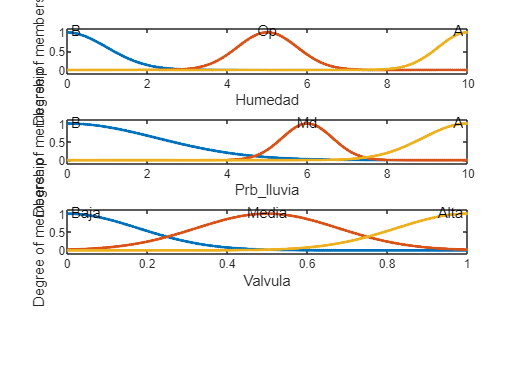


%Funciones plot: 
tiledlayout(4,1)
nexttile
plotmf(fuzziFIS, 'input', 1 ,1000)
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2); 
nexttile
plotmf(fuzziFIS, 'input', 2 ,1000)
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2); 
nexttile
plotmf(fuzziFIS, 'output', 1 ,1000)
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2); 

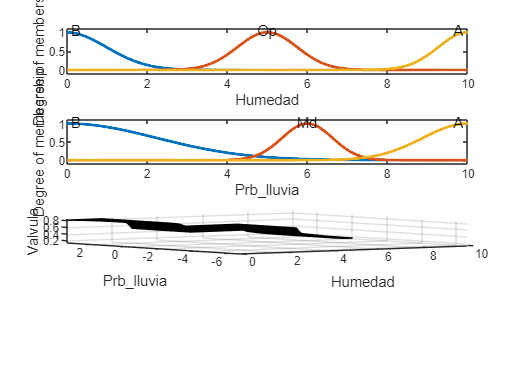


gensurf(fuzziFIS, options); 
set(findall(gca,'Type', 'Line'), 'LineWidth', 3); 
grid on